clear;
if exist('DataSet','dir')
   rmdir('.\DataSet\', 's');
end

mkdir('.\DataSet\');

% 配置
global run_type;
run_type = 'io';
config;

L_recTre = 119.0309


% 产生信号
source;
tag;
global y_sig;
y_sig = y_source;

% % dB 单位信噪比
% y_noise = awgn(y_sig, 50);
% y_sig = y_noise;

global Length;
global Width;

## 房间内的随机点(测试集)

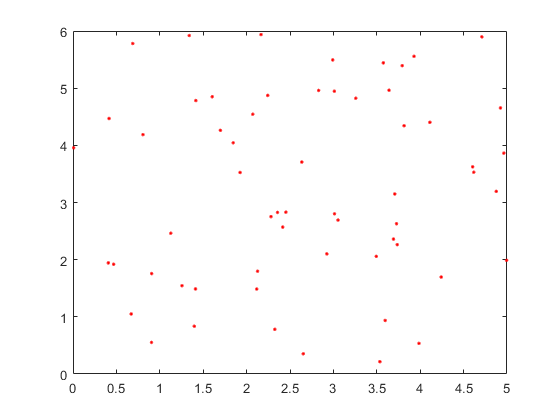

N_inside = 60;
x = Width * rand(1, N_inside);
y = Length * rand(1, N_inside);
figure; plot(x,y,'r.');


% 计算三个距离
for j=1:2
    [d1, d2, d3] = xy2d(x, y,j, 'inside');
    single_run(d1, d2, d3, false, 'inside', j);
end

L_tag is
  列 1 至 14

   99.9858  105.9570  108.9910  110.1228  105.3802  106.1900   99.6787  104.2026   99.1988  104.2495  111.4418  111.0742  110.7841  107.9806

  列 15 至 28

  106.6797  105.6764  105.9663  103.3830  104.7304  103.8875   99.9542   98.4446  107.8877  102.4016  108.5833  101.4073  103.4110  107.9893

  列 29 至 42

   99.4086   96.0447  104.3308   99.7748  101.0932  108.1518  109.3963  102.8619  105.5667  109.3401  109.0910  107.8111  111.2141  100.4501

  列 43 至 56

  103.4547  103.5884  108.3672  107.7213  101.0404  100.4880  107.8869  104.0764   99.3097  107.2691  101.2543  110.1464  102.8416  107.7521

  列 57 至 60

  111.2261  101.8453  105.8462  101.1061

delta t is
   1.0e-07 *

  列 1 至 14

    0.0152    0.1048    0.1523    0.1723    0.0966    0.1149    0.0169    0.0819    0.0253    0.0649    0.2122    0.1937    0.1860    0.1423

  列 15 至 28

    0.1147    0.0895    0.0922    0.0691    0.0745    0.0590    0.0145    0.0119    0.1274    0.0451    0.1523    0.0377    0

Rate_miss = 0

L_tag is
  列 1 至 14

  100.0255  106.0213  109.0256  110.1481  105.4516  106.2605   99.8306  104.2235   99.2260  104.2876  111.4722  111.0974  110.8056  108.0311

  列 15 至 28

  106.7347  105.7049  105.9996  103.4831  104.7845  103.9299   99.9944   98.6647  107.9120  102.4899  108.6285  101.4376  103.4382  108.0070

  列 29 至 42

   99.4309   96.6423  104.3724  100.0593  101.1170  108.1905  109.4150  102.9604  105.5842  109.3551  109.1337  107.8380  111.2401  100.4858

  列 43 至 56

  103.4852  103.7185  108.3821  107.7521  101.0719  100.6565  107.9333  104.1191   99.4540  107.2936  101.3024  110.1712  102.9080  107.7773

  列 57 至 60

  111.2427  101.9515  105.8810  101.2592

delta t is
   1.0e-07 *

  列 1 至 14

    0.0158    0.1056    0.1529    0.1728    0.0974    0.1158    0.0182    0.0824    0.0258    0.0655    0.2127    0.1942    0.1865    0.1430

  列 15 至 28

    0.1154    0.0901    0.0928    0.0701    0.0752    0.0596    0.0151    0.0134    0.1279    0.0460    0.1530    0.0383    0

Rate_miss = 0

## 房间周围的随机点

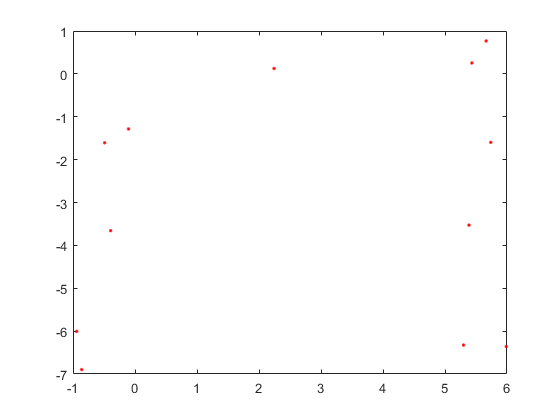

% 1/4 的数量
N_outside = 3;
x0 = rand(4, N_outside);
y0 = rand(4, N_outside);

x0 = [((Width / 2 + 1) * x0(:, 1:floor(N_outside / 2)))   (Width / 2 + x0(:, round(N_outside / 2) : end))];
y0 = [(Length / 2 + y0(:, 1:floor(N_outside / 2)))  ((Length / 2 + 1) * y0(:, round(N_outside / 2): end))];

x0(1,:) = -1 * x0(1, :);
x0(3,:) = -1 * x0(3, :);
y0(3,:) = -1 * y0(3, :);
y0(4,:) = -1 * y0(4, :);

% 坐标原点
x0 = x0 - (-1) * (Width / 2) * ones(size(x0));
y0 = y0 - 1 * (Length / 2) * ones(size(y0));

% 画出散点
figure; plot(x0,y0,'r.');


% 计算三个距离
for j=1:2
    [d1_0, d2_0, d3_0] = xy2d(x0, y0, j, 'outside');
    SinglePoint2(x0, y0, d1_0, d2_0, d3_0, false, 'outside', j);
end

  147.4162  118.8590  119.6454
  174.9151  228.4073  170.0700
  117.6507  120.4105  119.9111
  178.0985  166.7902  221.2545

delta t is
   1.0e-07 *

    0.1027    0.0171    0.0174
    0.2884    0.2433    0.2615
    0.0450    0.0819    0.0106
    0.2937    0.2551    0.2159

  147.4483  118.8893  119.6798
  174.9328  228.4335  170.0900
  118.1067  120.7284  120.0216
  178.1175  166.8143  221.2934

delta t is
   1.0e-07 *

    0.1031    0.0177    0.0179
    0.2887    0.2437    0.2618
    0.0472    0.0837    0.0117
    0.2942    0.2556    0.2164



## 上下房间

N_up = 10;
x_u = Width * rand(1, N_up);
y_u = Length * rand(1, N_up);
figure; plot(x,y,'r.');


% 计算三个距离
for j=1:2
    [d1_u, d2_u, d3_u] = xy2d(x, y,j, 'up');
    single_run(d1_u, d2_u, d3_u, false, 'up', j);
end

L_tag is
  列 1 至 14

  118.9013  125.9650  128.9316  130.0298  125.4026  126.2379  119.7834  123.4337  116.8989  123.9255  131.4260  130.9967  130.6793  127.9859

  列 15 至 28

  126.6646  125.3427  125.7304  123.4593  124.6129  123.5858  118.8806  118.7510  127.6686  122.3630  128.5773  120.3693  122.7326  127.6501

  列 29 至 42

  116.5582  117.3527  124.0618  120.3615  119.5367  128.0908  129.1855  122.9055  124.9067  129.0471  129.0861  127.6215  131.1632  119.3553

  列 43 至 56

  122.8779  123.7957  127.9839  127.5731  119.9481  120.7131  127.8657  123.7974  119.3491  127.0070  120.6915  130.0494  122.6861  127.5371

  列 57 至 60

  131.0803  121.8700  125.6211  121.3015

delta t is
   1.0e-07 *

  列 1 至 14

    0.0069    0.1033    0.1504    0.1700    0.0951    0.1138    0.0153    0.0749    0.0127    0.0606    0.2108    0.1916    0.1836    0.1410

  列 15 至 28

    0.1130    0.0851    0.0885    0.0678    0.0718    0.0549    0.0063    0.0112    0.1239    0.0429    0.1509    0.0295    0

Rate_miss = 0.9000

L_tag is
  列 1 至 14

  118.8549  125.8905  128.8911  130.0001  125.3201  126.1563  119.6128  123.4091  116.8670  123.8809  131.3903  130.9693  130.6539  127.9270

  列 15 至 28

  126.6006  125.3093  125.6915  123.3448  124.5499  123.5363  118.8335  118.5097  127.6400  122.2616  128.5246  120.3338  122.7005  127.6292

  列 29 至 42

  116.5319  116.7736  124.0131  120.0564  119.5088  128.0455  129.1635  122.7927  124.8860  129.0294  129.0362  127.5900  131.1326  119.3135

  列 43 至 56

  122.8421  123.6485  127.9663  127.5368  119.9112  120.5250  127.8115  123.7475  119.1866  126.9782  120.6354  130.0203  122.6092  127.5074

  列 57 至 60

  131.0606  121.7488  125.5802  121.1296

delta t is
   1.0e-07 *

  列 1 至 14

    0.0062    0.1023    0.1497    0.1694    0.0941    0.1128    0.0138    0.0743    0.0120    0.0599    0.2102    0.1911    0.1831    0.1401

  列 15 至 28

    0.1121    0.0845    0.0878    0.0666    0.0709    0.0541    0.0055    0.0094    0.1233    0.0417    0.1501    0.0289    0

Rate_miss = 0.9000


N_dn = 10;
x_d = Width * rand(1, N_dn);
y_d = Length * rand(1, N_dn);
figure; plot(x,y,'r.');


% 计算三个距离
for j=1:2
    [d1_d, d2_d, d3_d] = xy2d(x, y,j, 'down');
    single_run(d1_d, d2_d, d3_d, false, 'down', j);
end

L_tag is
  列 1 至 14

  128.5166  131.1664  132.8006  133.5052  130.8899  131.4371  128.3398  130.7044  129.0327  130.0442  134.5426  134.1632  133.9599  132.3495

  列 15 至 28

  131.5099  130.8894  130.9464  129.9910  130.2727  129.8310  128.4895  128.2124  132.1239  129.2556  132.6837  129.2838  130.0323  132.4425

  列 29 至 42

  129.5137  128.9904  130.0478  129.5957  129.6606  132.2751  133.1386  129.6417  131.4543  133.3074  133.0099  132.0373  134.2904  128.7838

  列 43 至 56

  129.9056  130.5631  132.8368  131.9534  129.1250  128.9662  132.2062  129.9175  128.0834  131.7870  128.6903  133.5202  129.3178  132.0296

  列 57 至 60

  134.3258  129.1215  130.8679  129.1885

delta t is
   1.0e-07 *

  列 1 至 14

    0.1397    0.2016    0.2368    0.2526    0.1958    0.2110    0.1402    0.1895    0.1539    0.1698    0.2876    0.2704    0.2640    0.2310

  列 15 至 28

    0.2085    0.1888    0.1896    0.1767    0.1765    0.1652    0.1391    0.1399    0.2172    0.1569    0.2385    0.1565    0

Rate_miss = 1

L_tag is
  列 1 至 14

  128.6220  131.3004  132.8979  133.5851  131.0301  131.5767  128.5195  130.7745  129.1165  130.1472  134.6327  134.2389  134.0315  132.4694

  列 15 至 28

  131.6347  130.9758  131.0415  130.1501  130.3966  129.9403  128.5958  128.4071  132.2019  129.4079  132.7968  129.3736  130.1163  132.5048

  列 29 至 42

  129.5872  129.2110  130.1560  129.7990  129.7372  132.3791  133.2034  129.8000  131.5161  133.3623  133.1196  132.1204  134.3719  128.8830

  列 43 至 56

  129.9957  130.7356  132.8914  132.0443  129.2170  129.1504  132.3209  130.0273  128.2608  131.8653  128.8072  133.5991  129.4538  132.1094

  列 57 至 60

  134.3852  129.2838  130.9657  129.3685

delta t is
   1.0e-07 *

  列 1 至 14

    0.1420    0.2042    0.2390    0.2545    0.1984    0.2136    0.1432    0.1913    0.1559    0.1720    0.2897    0.2723    0.2658    0.2334

  列 15 至 28

    0.2110    0.1908    0.1917    0.1795    0.1789    0.1675    0.1414    0.1429    0.2192    0.1597    0.2409    0.1586    0

Rate_miss = 1

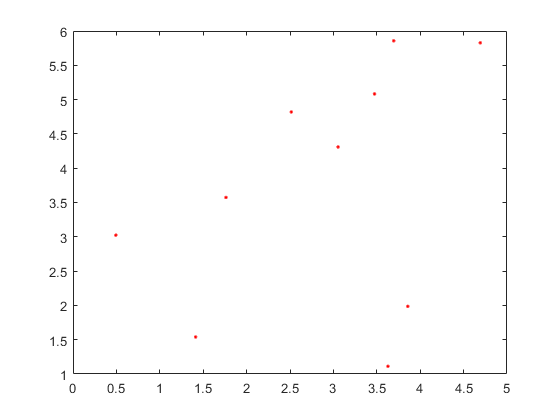

% 画出散点
figure; plot(x_u,y_u,'r.');

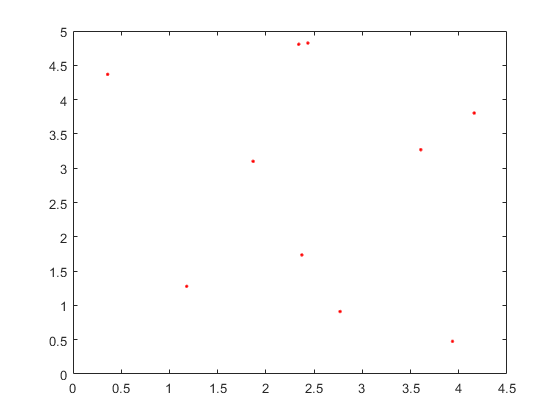

figure; plot(x_d,y_d,'r.');

## 保存数据集的信息

% 保存样本点
filename = '.\DataSet\sample.mat'

filename = '.\DataSet\sample.mat'

save(filename, 'N_inside', 'N_outside', 'N_up', 'N_dn',...
    'x', 'y', 'd1', 'd2', 'd3', ...
    'x0', 'y0', 'd1_0', 'd2_0', 'd3_0', ...
    'x_u', 'y_u', 'd1_u', 'd2_u', 'd3_u', ...
    'x_d', 'y_d', 'd1_d', 'd2_d', 'd3_d');

## 数据预处理

% [] = preproc(filename, i, draw, isBeacon)
for i=1: N_inside
    preproc('i_sig_rx', i, false, 'inside');
end

% outside
for i=1: 4 * N_outside
    preproc('o_sig_rx', i, false, 'outside');
end

% up
for i=1: N_up
    preproc('u_sig_rx', i, false, 'up');
end

% down
for i=1: N_dn
    preproc('d_sig_rx', i, false, 'down');
end